# Gas Turbine Engine Interpolation Example

Consider a gas turbine engine where we are given a table of thrust values at different Mach numbers for a fixed altitude:

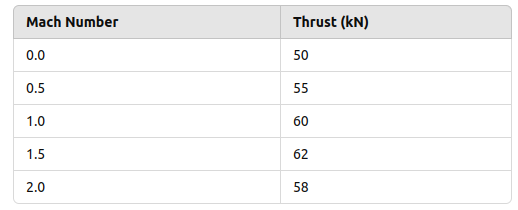

We want to estimate the thrust values we can expect for Mach 0.75 and 1.25.

### Linear Interpolation

Using linear interpolation, to estimate the thrust at the two given Mach numbers. Use `fprintf` to display the results as formatted output, including engineering units.

mach_numbers = [0.0, 0.5, 1.0, 1.5, 2.0];  % Mach numbers
thrust_values = [50, 55, 60, 62, 58];      % Corresponding thrust values in kN

% Points at which we want to estimate the thrust
mach_query = [0.75, 1.25];

% Linear interpolation
thrust_linear = interp1(mach_numbers, thrust_values, mach_query, 'linear');
% Display results
fprintf('Linear Interpolation Results:\n');

Linear Interpolation Results:


fprintf('Thrust at Mach 0.75: %.2f kN\n', thrust_linear(1));

Thrust at Mach 0.75: 57.50 kN


fprintf('Thrust at Mach 1.25: %.2f kN\n', thrust_linear(2));

Thrust at Mach 1.25: 61.00 kN


### Spline Interpolation

Using spline interpolation, to estimate the thrust at the two given Mach numbers. Use `fprintf` to display the results as formatted output, including engineering units.


% Cubic spline interpolation
thrust_spline = interp1(mach_numbers, thrust_values, mach_query, 'spline');

fprintf('\nCubic Spline Interpolation Results:\n');


Cubic Spline Interpolation Results:


fprintf('Thrust at Mach 0.75: %.2f kN\n', thrust_spline(1));

Thrust at Mach 0.75: 57.69 kN


fprintf('Thrust at Mach 1.25: %.2f kN\n', thrust_spline(2));

Thrust at Mach 1.25: 61.56 kN


### Plot the Results

Generate a plot, with axis labels, legend, etc. that includes the following

- The original data points from the table.

- The linear interpolation values

- The cubic spline interpolation values.

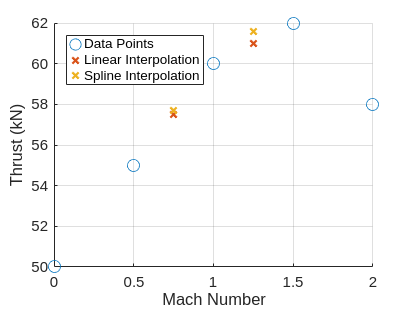

% Plotting the results
figure;
hold on;
grid on;

% Plot the original data points
plot(mach_numbers, thrust_values, 'o', 'MarkerSize', 8, 'DisplayName', 'Data Points');

% Plot the linear interpolation line
plot(mach_query, thrust_linear, 'x', 'LineWidth', 1.5, 'DisplayName', 'Linear Interpolation');

% Plot the cubic spline interpolation
plot(mach_query, thrust_spline, 'x', 'LineWidth', 1.5, 'DisplayName', 'Spline Interpolation');

% Adding labels and legend
xlabel('Mach Number');
ylabel('Thrust (kN)');
legend('Location', 'NorthWest');
hold off;